clear
% SNR in plots are power SNRs
% number_averages = 2000; % number of averages for waveforms (averaging
% waveforms then phase). Use either this or the below 2 lines

number_averages_phase = 25000;  % if averaging phase directly
latched_hold_time = 1e-6; % when performing latching experiment, latched data collected and averaged for this long.
% this is then plotted in a separate histogram
number_averages = round(number_averages_phase/16); % convert back to number of waveforms to decide on length (time) of signal

number_iterations = 1; % calculate averaged phase for this many different iterations of noise.
sin_wave_amp = .562e-3;   % amplitude of the clean input sin wave. not as important as the SNR.
snr = 1;   % this is SNR of power.SNR of the white noise signal. This is only BW limited by the sampling frequency (sampling_freq/2)
% snr = .1;
% this number will be further increased by a factor of ~7 by the analog BPFs
snr = sqrt(snr)  % voltage SNR, so sd of noise can be calculated directly.

snr = 1

phase_0= -90 * pi/180;  % phase of state 0 of the clean rts signal
phase_1 = 50* pi/180 + phase_0; % phase of state 1 of the clean rts signal
if_freq = 21e6;   % frequency of the simulated clean sin wave
sampling_freq = 168e6;   % sampling frequency of the signal
average_number_latched = latched_hold_time * sampling_freq;  % number of points that get averaged into one phase 
%point before plotting as histogram
average_emission_time = 25e-6;   % average time in state 0 (Poisson distributed)
average_capture_time = 35e-6;    % average time in state 1 
pass_band_start_chebyshev = 19.25e6;  % pass band of the digital Chebyshev filter
pass_band_stop_chebyshev = 22.75e6;
pass_band_start_inbuilt = 20e6;  % pass band of the digital inbuilt filter
pass_band_stop_inbuilt = 22e6;
noise_bw = 10e6;   % BW limit the input white noise above. Limited because of the analog BPFs (SBP 21.4+) - simulating that effect.
% The SNR after this filtering stage is the true single shot SNR in our experiment
% (calculated from the noise temp)
noise_band_start = if_freq - noise_bw/2; 
noise_band_stop = if_freq + noise_bw/2;

sd_noise_white = sin_wave_amp/snr;  % standard deviation of the white noise calculated from the SNR and the input sin wave amp

total_time = 2/if_freq * number_averages;   % length (Time) of signal 
time = 0: 1/sampling_freq: total_time - 1/sampling_freq;  % time points in signal sampled at sampling_freq
[time_out, rts_out] = generate_rts(time, average_capture_time, average_emission_time);
phase = zeros(1,length(rts_out));
phase (rts_out == 1) = phase_1;
phase(rts_out == 0) = phase_0;
clean_sin_wave = sin_wave_amp*sin(2*pi*if_freq*time + phase);  % clean sin wave as defined by params above. 

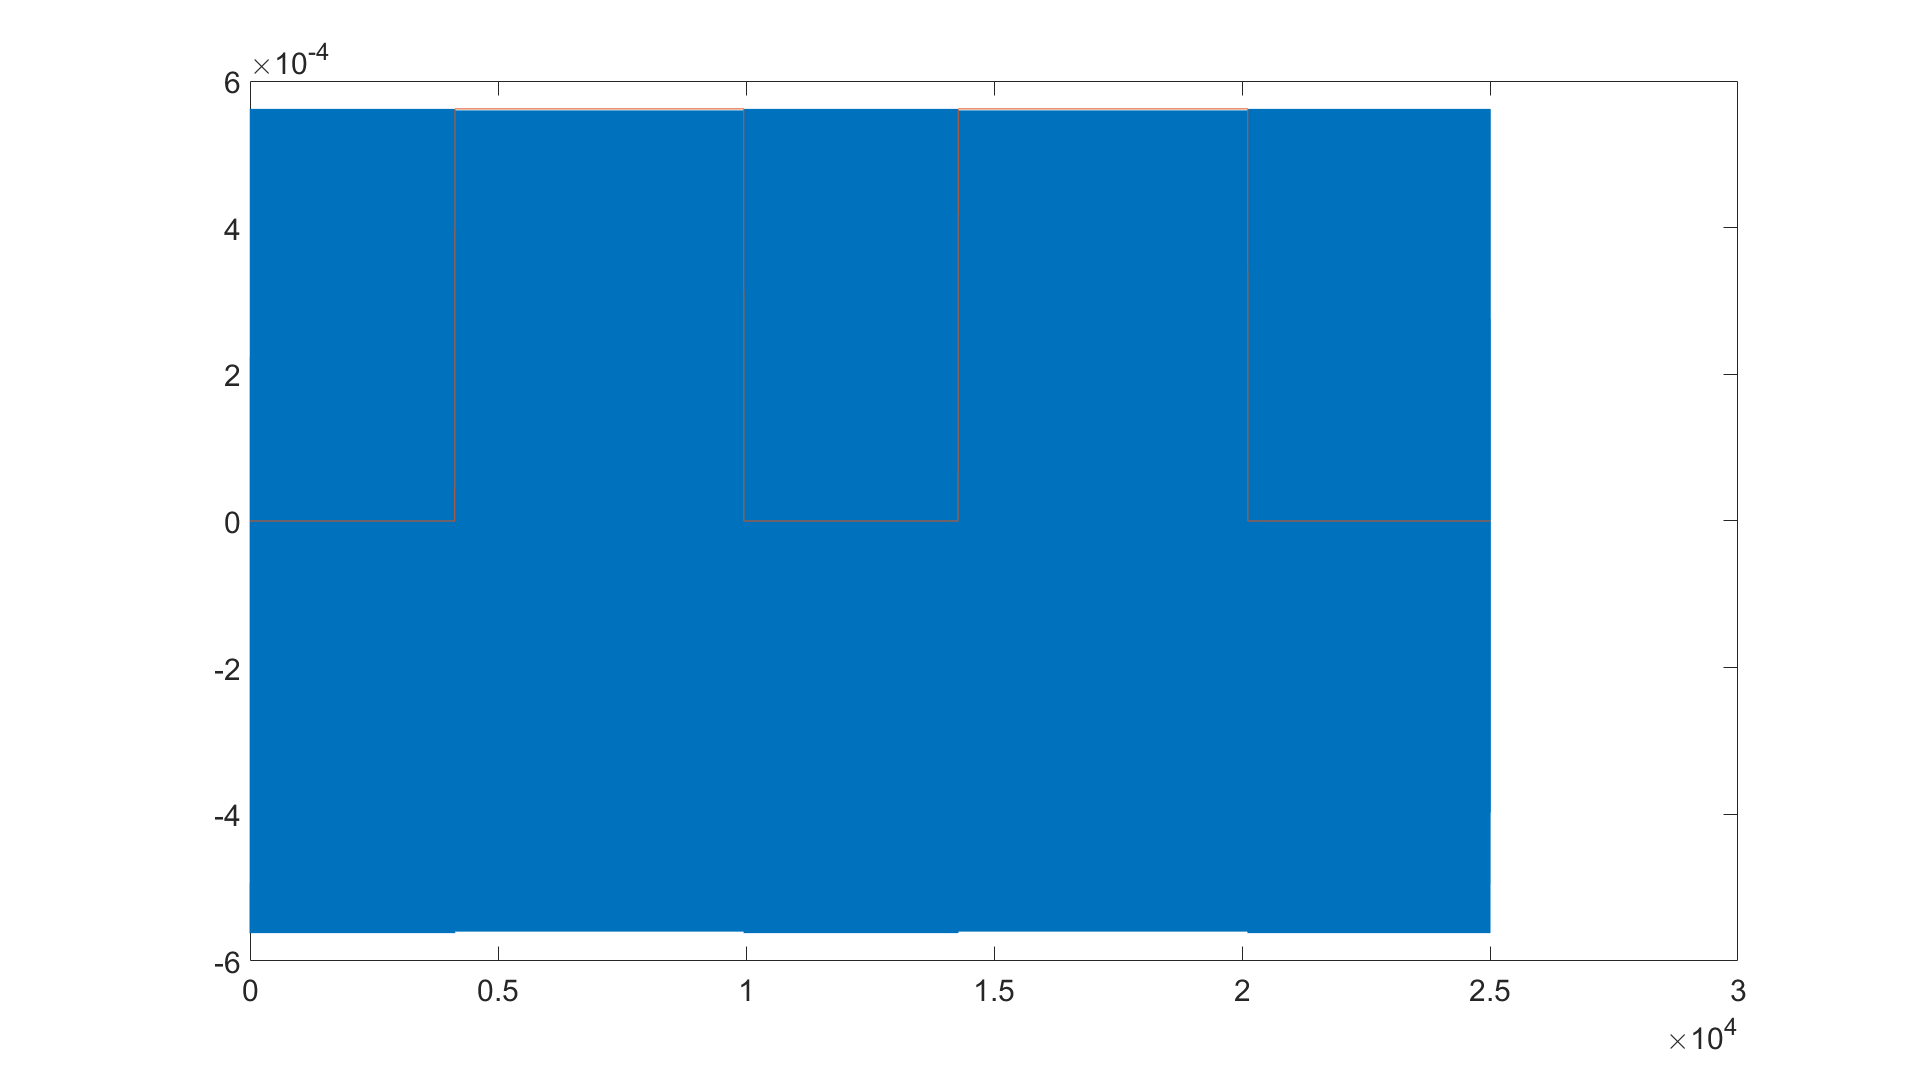

figure
plot(clean_sin_wave)
hold on
plot(rts_out *sin_wave_amp)

% initiate arrays %
noise_white = zeros(number_iterations, length(time));
noise = noise_white;
noisy_signal = noise; 
filtered_noise_inbuilt = noise;
filtered_noise_chebyshev = noise;
filtered_signal_inbuilt = noise;
filtered_signal_chebyshev = noise;
envelope_amp_total = noise;
envelope_phase_total = noise;
envelope_amp_total_filtered_inbuilt = noise; 
envelope_phase_total_filtered_inbuilt = noise;
envelope_amp_total_filtered_chebyshev = noise;
envelope_phase_total_filtered_chebyshev = noise;

averaged_signal = zeros(number_iterations, 2*sampling_freq/if_freq);
averaged_signal_filtered_inbuilt = averaged_signal;
envelope_amp = averaged_signal;
envelope_phase = averaged_signal;
envelope_amp_filtered_inbuilt = averaged_signal;
envelope_phase_filtered_inbuilt = averaged_signal;

freqs = zeros(number_iterations, length(time)/2 + 1);
psd = freqs;
psd_white = freqs;
freqs_white = freqs;
freqs_noise_filtered_inbuilt = freqs;
psd_noise_filtered_inbuilt = freqs;
freqs_noise_filtered_chebyshev = freqs;
psd_noise_filtered_chebyshev = freqs;

mean_phase = zeros(number_iterations,1);
std_phase = mean_phase;
mean_phase_total = mean_phase;
std_phase_total = mean_phase;
mean_phase_filtered_inbuilt = mean_phase;
std_phase_filtered_inbuilt = mean_phase;
mean_phase_total_filtered_inbuilt = mean_phase;
std_phase_total_filtered_inbuilt = mean_phase;
mean_phase_total_filtered_chebyshev = mean_phase;
std_phase_total_filtered_chebyshev = mean_phase;

for i = 1:number_iterations   % run loop for number_iterations iterations of noise.
    
    % generate white noise, BW limited by sampling_freq
    noise_white(i,:) = sd_noise_white * randn(1,length(time));
    [freqs_white(i,:), psd_white(i,:)] = extract_PSD(time, noise_white(i,:));
    
    % BW limit white hoise to within the analog SBPT 21.4+ filter BW,
    % extract PSD of this noise after passing through digital filters also
    noise(i,:) = bandpass(noise_white(i,:), [noise_band_start, noise_band_stop], sampling_freq);
    [freqs(i,:), psd(i,:)] = extract_PSD(time, noise(i,:));
    [filtered_noise_inbuilt(i,:), D] = bandpass(noise(i,:),[pass_band_start_inbuilt pass_band_stop_inbuilt],sampling_freq);
    [filtered_noise_chebyshev(i,:), T] = second_order_chebyshev_filter(noise(i,:), sampling_freq, pass_band_start_chebyshev, pass_band_stop_chebyshev);
%     [filtered_noise_chebyshev(i,:)] = zeros(size(noise(i,:)));
    [freqs_noise_filtered_inbuilt(i,:), psd_noise_filtered_inbuilt(i,:)] = extract_PSD(time, filtered_noise_inbuilt(i,:));
    [freqs_noise_filtered_chebyshev(i,:), psd_noise_filtered_chebyshev(i,:)] = extract_PSD(time, filtered_noise_chebyshev(i,:));
    
    % generate noisy signal for this iteration, and filter using the inbuilt
    % bandpass function, and the Chebyshev 2nd order filter
    noisy_signal(i,:) = clean_sin_wave + noise(i,:);
    filtered_signal_inbuilt(i,:) = bandpass(noisy_signal(i,:),[pass_band_start_inbuilt pass_band_stop_inbuilt],sampling_freq);
    filtered_signal_chebyshev(i,:) = second_order_chebyshev_filter(noisy_signal(i,:), sampling_freq, pass_band_start_chebyshev, pass_band_stop_chebyshev);
%     filtered_signal_chebyshev(i,:) = filtered_noise_chebyshev(i,:);    

    % averaging waveforms then phase extraction
    signal_reshaped = reshape(noisy_signal(i,:), 2*sampling_freq/if_freq,[]);    
    signal_reshaped_filtered_inbuilt = reshape(filtered_signal_inbuilt(i,:), 2*sampling_freq/if_freq,[]);
    averaged_signal_filtered_inbuilt(i,:) = mean(signal_reshaped_filtered_inbuilt,2);    
    averaged_signal (i,:)= mean(signal_reshaped, 2);    
    
    [envelope_amp(i,:), envelope_phase(i,:)] = get_amp_and_phase(time(1,1:2*sampling_freq/if_freq), averaged_signal(i,:), if_freq, sampling_freq);    
    [envelope_amp_filtered_inbuilt(i,:), envelope_phase_filtered_inbuilt(i,:)] = get_amp_and_phase(time(1,1:2*sampling_freq/if_freq), averaged_signal_filtered_inbuilt(i,:), if_freq, sampling_freq);
    
    % extract phase directly
    [envelope_amp_total(i,:), envelope_phase_total(i,:)] = get_amp_and_phase(time, noisy_signal(i,:), if_freq, sampling_freq);    
    [envelope_amp_total_filtered_inbuilt(i,:), envelope_phase_total_filtered_inbuilt(i,:)] = get_amp_and_phase(time, filtered_signal_inbuilt(i,:), if_freq, sampling_freq);
    [envelope_amp_total_filtered_chebyshev(i,:), envelope_phase_total_filtered_chebyshev(i,:)] = get_amp_and_phase(time, filtered_signal_chebyshev(i,:), if_freq, sampling_freq);
    
    % mean and std of phase for ith iteration
    
    % averaged waveforms before phase
    mean_phase(i) = 180/pi*circ_mean(envelope_phase(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2)'); % the circ function finds mean of circular quantities
    std_phase(i) = 180/pi*circ_std(envelope_phase(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2)'); % only take average of middle waveform. ignore edge effects of digital IQ
%     mean_phase(i) = 180/pi*atan2(mean(sin(envelope_phase(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2))), mean(cos(envelope_phase(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2))));
%     std_phase(i) = 180/pi*std(envelope_phase(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2));
    
    mean_phase_filtered_inbuilt(i) = 180/pi*circ_mean(envelope_phase_filtered_inbuilt(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2)');
    std_phase_filtered_inbuilt(i) = 180/pi*circ_std(envelope_phase_filtered_inbuilt(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2)');
%     mean_phase_filtered_inbuilt(i) = 180/pi*atan2(mean(sin(envelope_phase_filtered_inbuilt(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2))), mean(cos(envelope_phase_filtered_inbuilt(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2))));
%     std_phase_filtered_inbuilt(i) = 180/pi*std(envelope_phase_filtered_inbuilt(i,sampling_freq/if_freq/2 + 1:end - sampling_freq/if_freq/2));
    
    % average of extracted phases 
    mean_phase_total(i) = 180/pi*circ_mean(envelope_phase_total(i,:)');
    std_phase_total(i) = 180/pi*circ_std(envelope_phase_total(i,:)');
%     mean_phase_total(i) = 180/pi*atan2(mean(sin(envelope_phase_total(i,:))), mean(cos(envelope_phase_total(i,:))));
%     std_phase_total(i) = 180/pi*std(envelope_phase_total(i,:));
        
    mean_phase_total_filtered_inbuilt(i) = 180/pi*circ_mean(envelope_phase_total_filtered_inbuilt(i,:)');
    std_phase_total_filtered_inbuilt(i) = 180/pi*circ_std(envelope_phase_total_filtered_inbuilt(i,:)');
%     mean_phase_total_filtered_inbuilt(i) = 180/pi*atan2(mean(sin(envelope_phase_total_filtered_inbuilt(i,:))), mean(cos(envelope_phase_total_filtered_inbuilt(i,:))));
%     std_phase_total_filtered_inbuilt(i) = 180/pi*std(envelope_phase_total_filtered_inbuilt(i,:));
    
    mean_phase_total_filtered_chebyshev(i) = 180/pi*circ_mean(envelope_phase_total_filtered_chebyshev(i,:)');
    std_phase_total_filtered_chebyshev(i) = 180/pi*circ_std(envelope_amp_total_filtered_chebyshev(i,:)');
%     mean_phase_total_filtered_chebyshev(i) = 180/pi*atan2(mean(sin(envelope_phase_total_filtered_chebyshev(i,:))), mean(cos(envelope_phase_total_filtered_chebyshev(i,:))));
%     std_phase_total_filtered_chebyshev(i) = 180/pi*std(envelope_phase_total_filtered_chebyshev(i,:));
end

% mean and std of extracted phase for each iteration over all iterations
% iterations_mean_unfiltered_average_waveforms = 180/pi*atan2(mean(sin(pi/180*mean_phase)), mean(cos(pi/180*mean_phase)));
% iterations_mean_filtered_inbuilt_average_waveforms = 180/pi*atan2(mean(sin(pi/180*mean_phase_filtered_inbuilt)), mean(cos(pi/180*mean_phase_filtered_inbuilt)));
% iterations_mean_unfiltered_average_phases = 180/pi*atan2(mean(sin(pi/180*mean_phase_total)), mean(cos(pi/180*mean_phase_total)));
% iterations_mean_filtered_inbuilt_average_phases = 180/pi*atan2(mean(sin(pi/180*mean_phase_total_filtered_inbuilt)), mean(cos(pi/180*mean_phase_total_filtered_inbuilt)));
% iterations_mean_filtered_chebyshev_average_phases = 180/pi*atan2(mean(sin(pi/180*mean_phase_total_filtered_chebyshev)), mean(cos(pi/180*mean_phase_total_filtered_chebyshev)));

iterations_mean_unfiltered_average_waveforms = 180/pi*circ_mean(pi/180*mean_phase);
iterations_mean_filtered_inbuilt_average_waveforms = 180/pi*circ_mean(pi/180*mean_phase_filtered_inbuilt);
iterations_mean_unfiltered_average_phases = 180/pi*circ_mean(pi/180*mean_phase_total);
iterations_mean_filtered_inbuilt_average_phases = 180/pi*circ_mean(pi/180*mean_phase_total_filtered_inbuilt);
iterations_mean_filtered_chebyshev_average_phases = 180/pi*circ_mean(pi/180*mean_phase_total_filtered_chebyshev);
iterations_std_unfiltered_average_waveforms = 180/pi*circ_std(pi/180*mean_phase);
iterations_std_filtered_inbuilt_average_waveforms = 180/pi*circ_std(pi/180*mean_phase_filtered_inbuilt);
iterations_std_unfiltered_average_phases = 180/pi*circ_std(pi/180*mean_phase_total);
iterations_std_filtered_inbuilt_average_phases = 180/pi*circ_std(pi/180*mean_phase_total_filtered_inbuilt);
iterations_std_filtered_chebyshev_average_phases = 180/pi*circ_std(pi/180*mean_phase_total_filtered_chebyshev);

max_number = 40;   % find the max how many while trying to decide the max value of the perfect filter
chebyshev_how_many = 0;  % Chebyshev filter some times has peaks at the edges of the pass band. To omit plotting those peaks

% characteristics of white noise only limited by sampling freq
sd_white_noise = std(noise_white(1,:))   %

sd_white_noise = 5.6311e-04

snr_white_noise = (sin_wave_amp/sd_white_noise)^2   % power SNR

snr_white_noise = 0.9961

% max_white_noise = maxk(abs(mean(psd_white,1)).^2 , 4); % to get rid of the signal density point, select 4th highest
% calculate Equivalent Noise BW from Ott 8-11
enbw_white_noise = (1/median(mean(psd_white,1))^2 * sum(abs(mean(psd_white,1).^2) * mean(diff(squeeze(freqs_white(i,:)))))/1e6) 

enbw_white_noise = 348.0747


% characteristics of analog BW limited noise 
sd_bw_limited_noise = std(noise(1,:))

sd_bw_limited_noise = 2.1399e-04

snr_bw_limited_noise = (sin_wave_amp/sd_bw_limited_noise)^2

snr_bw_limited_noise = 6.8974

factor_improvement_snr_bw_limited = snr_bw_limited_noise/snr_white_noise

factor_improvement_snr_bw_limited = 6.9246

max_bw_limited_noise = maxk(abs(mean(psd,1)).^2, max_number); % to get rid of the signal density point, select 4th highest
enbw_bw_limited_noise = 1/median(mean(psd_white,1))^2 * sum(abs(mean(psd,1).^2)) * mean(diff(squeeze(freqs(1,:))))/1e6

enbw_bw_limited_noise = 47.1810

factor_improvement_enbw_bw_limited = enbw_white_noise/enbw_bw_limited_noise   % this improvement should be the inverse ratio of the respective ENBWs

factor_improvement_enbw_bw_limited = 7.3774

factor_improvement_snr_from_enbw_improvement_bw_limited = factor_improvement_enbw_bw_limited   % this should be same as snr_improvement_factor

factor_improvement_snr_from_enbw_improvement_bw_limited = 7.3774

psd_perfect_bw_limited_filtered = zeros(1,length(freqs(1,:)));
psd_perfect_bw_limited_filtered(freqs(1,:) > 21e6 - enbw_bw_limited_noise*1e6 /2 & freqs(1,:) < 21e6 + enbw_bw_limited_noise *1e6/2) = median(mean(psd_white,1));

% characteristics of inbuilt filtered noise
sd_inbuilt_filtered_noise = std(filtered_noise_inbuilt(1,:))

sd_inbuilt_filtered_noise = 1.2784e-04

snr_inbuilt_filtered_noise = (sin_wave_amp/sd_inbuilt_filtered_noise)^2   % power SNR

snr_inbuilt_filtered_noise = 19.3244

factor_improvement_snr_inbuilt_filtered = snr_inbuilt_filtered_noise/snr_white_noise % this improvement should be the inverse ratio of the respective ENBWs

factor_improvement_snr_inbuilt_filtered = 19.4006

max_inbuilt_filtered_noise = maxk(abs(mean(psd_noise_filtered_inbuilt,1)).^2, max_number); % to get rid of the signal density point, select 4th highest
enbw_inbuilt_filtered_noise = (1/median(mean(psd_white,1))^2 * sum(abs(mean(psd_noise_filtered_inbuilt,1).^2) * mean(diff(squeeze(freqs_noise_filtered_inbuilt(1,:)))))/1e6)

enbw_inbuilt_filtered_noise = 14.9515

factor_improvement_enbw_inbuilt_filtered = enbw_white_noise/enbw_inbuilt_filtered_noise

factor_improvement_enbw_inbuilt_filtered = 23.2803

factor_improvement_snr_from_enbw_improvement_inbuilt_filtered = factor_improvement_enbw_inbuilt_filtered % this should be same as snr_improvement_factor

factor_improvement_snr_from_enbw_improvement_inbuilt_filtered = 23.2803

psd_perfect_inbuilt_filtered = zeros(1,length(freqs_noise_filtered_inbuilt(1,:)));
psd_perfect_inbuilt_filtered(freqs_noise_filtered_inbuilt(1,:) > 21e6 - enbw_inbuilt_filtered_noise*1e6 /2 & freqs_noise_filtered_inbuilt(1,:) < 21e6 + enbw_inbuilt_filtered_noise *1e6/2) = median(mean(psd_white,1));

% characteristics of Chebyshev filtered noise
sd_chebyshev_filtered_noise = std(filtered_noise_chebyshev(1,:))

sd_chebyshev_filtered_noise = 1.2118e-04

snr_chebyshev_filtered_noise = (sin_wave_amp/sd_chebyshev_filtered_noise)^2

snr_chebyshev_filtered_noise = 21.5099

factor_improvement_snr_chebyshev_filtered = snr_chebyshev_filtered_noise/snr_white_noise 

factor_improvement_snr_chebyshev_filtered = 21.5947

[max_chebyshev_filtered_noise, chebyshev_indices] = maxk(abs(mean(psd_noise_filtered_chebyshev,1)).^2, max_number); % to get rid of the signal density point, select 4th highest
% don't plot peaks at edges of Chebyshev filter
if chebyshev_how_many ~= 0
    psd_noise_filtered_chebyshev(:,chebyshev_indices(1:chebyshev_how_many)) = mode(mode(psd_noise_filtered_chebyshev));
end
enbw_chebyshev_filtered_noise = (1/median(mean(psd_white,1))^2 * sum(abs(mean(psd_noise_filtered_chebyshev,1).^2) * mean(diff(squeeze(freqs_noise_filtered_chebyshev(1,:)))))/1e6)

enbw_chebyshev_filtered_noise = 15.6963

factor_improvement_enbw_inbuilt_filtered = enbw_white_noise/enbw_chebyshev_filtered_noise

factor_improvement_enbw_inbuilt_filtered = 22.1756

factor_improvement_snr_from_enbw_improvement_chebyshev_filtered = factor_improvement_enbw_inbuilt_filtered

factor_improvement_snr_from_enbw_improvement_chebyshev_filtered = 22.1756

psd_perfect_chebyshev_filtered = zeros(1,length(freqs_noise_filtered_chebyshev(1,:)));
psd_perfect_chebyshev_filtered(freqs_noise_filtered_chebyshev(1,:) > 21e6 - enbw_chebyshev_filtered_noise*1e6 /2 & freqs_noise_filtered_chebyshev(1,:) < 21e6 + enbw_chebyshev_filtered_noise *1e6/2) = median(mean(psd_white,1));

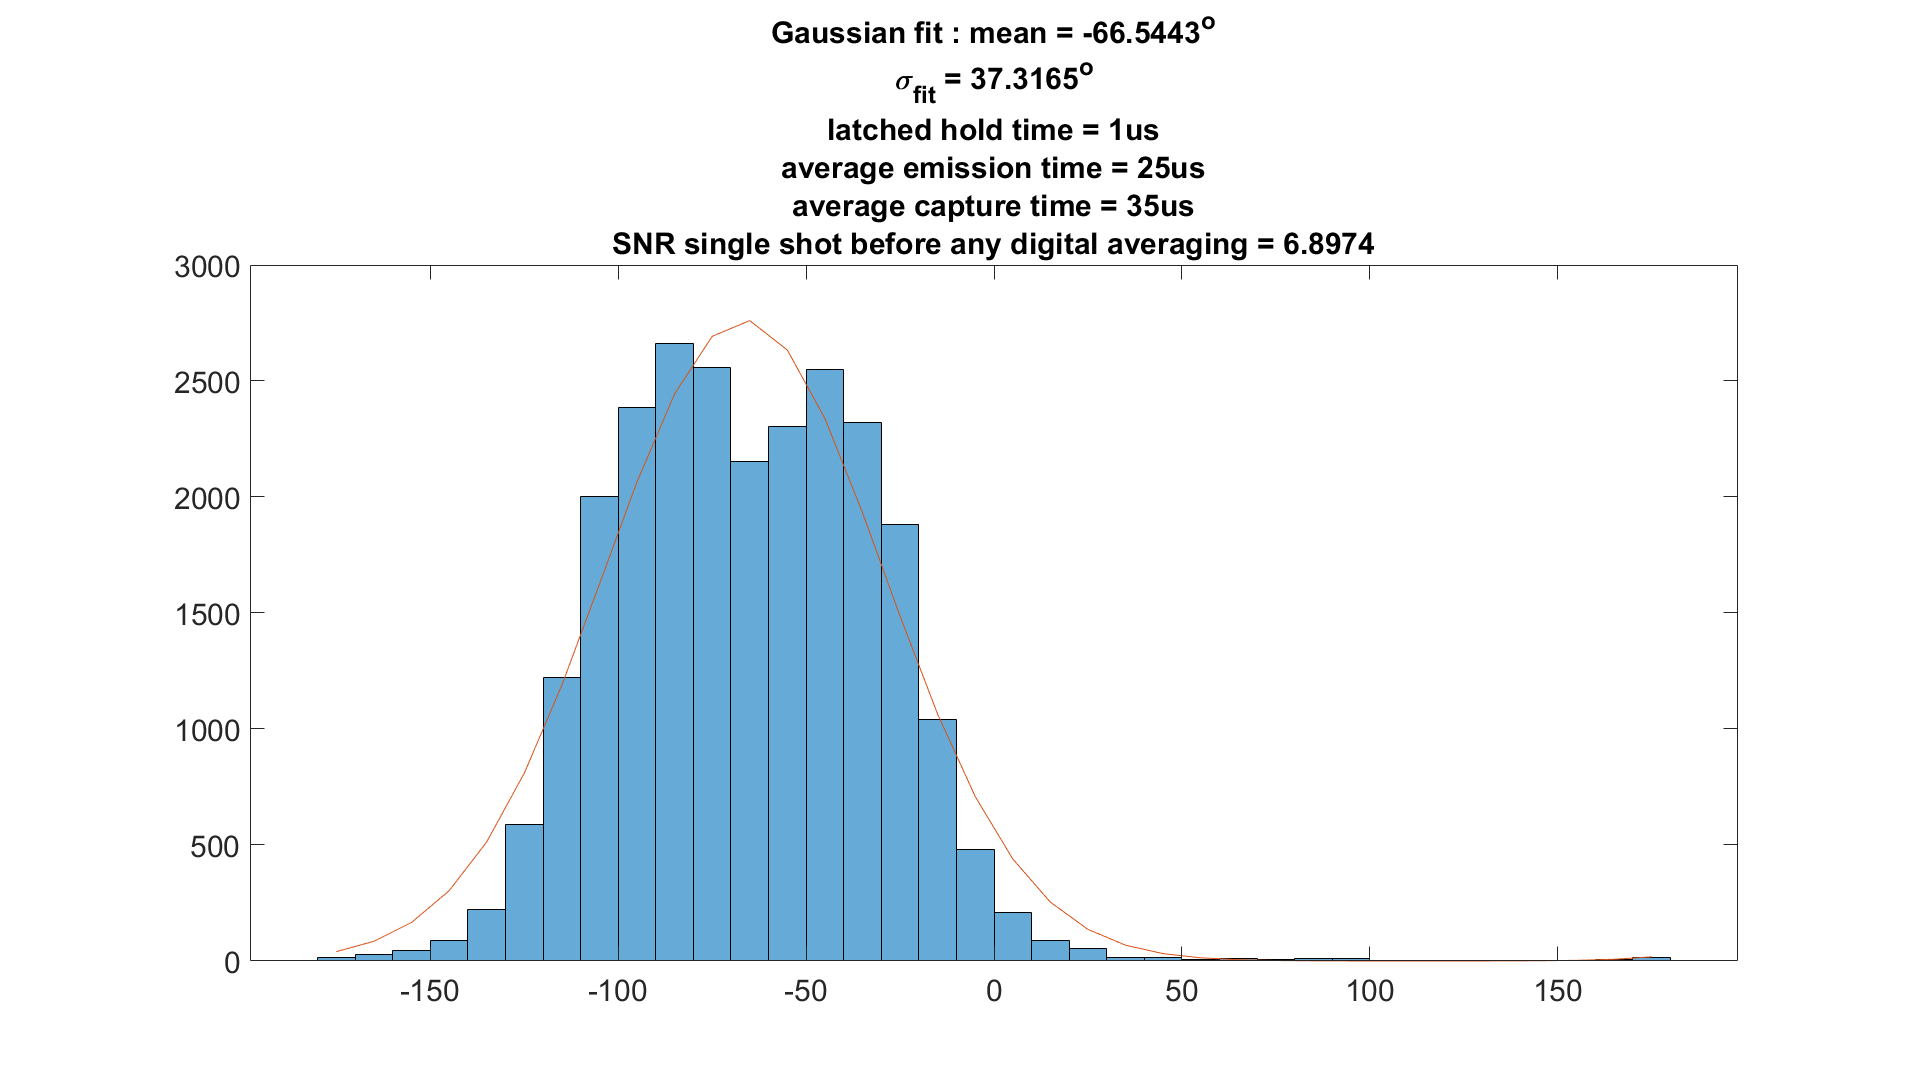

figure
unaveraged_histogram = histogram(180/pi*squeeze(envelope_phase_total(1,:)), 36);
bin_width = unaveraged_histogram.BinWidth;
bin_edges = unaveraged_histogram.BinEdges;
[~,I] = max(unaveraged_histogram.Values);
peak_angle = bin_edges(I) + bin_width/2;
[gaussian_fit_unaveraged, theory_gaussian_unaveraged] = fit_gaussian(wrapTo180(bin_edges(1:end - 1) + bin_width/2 - peak_angle), unaveraged_histogram.Values);
hold on
plot(wrapTo180(bin_edges(1:end - 1) + bin_width/2), theory_gaussian_unaveraged)
title(['Gaussian fit : mean = ' num2str(gaussian_fit_unaveraged(2) + peak_angle) '^o' 13 10 ...
    '\sigma_{fit} = ' num2str(gaussian_fit_unaveraged(3)) '^o' 13 10 ...
    'latched hold time = ' num2str(latched_hold_time*1e6) 'us' 13 10 ...
    'average emission time = ' num2str(average_emission_time*1e6) 'us' 13 10 ...
    'average capture time = ' num2str(average_capture_time*1e6) 'us' 13 10 ...
    'SNR single shot before any digital averaging = ' num2str(snr_bw_limited_noise)])

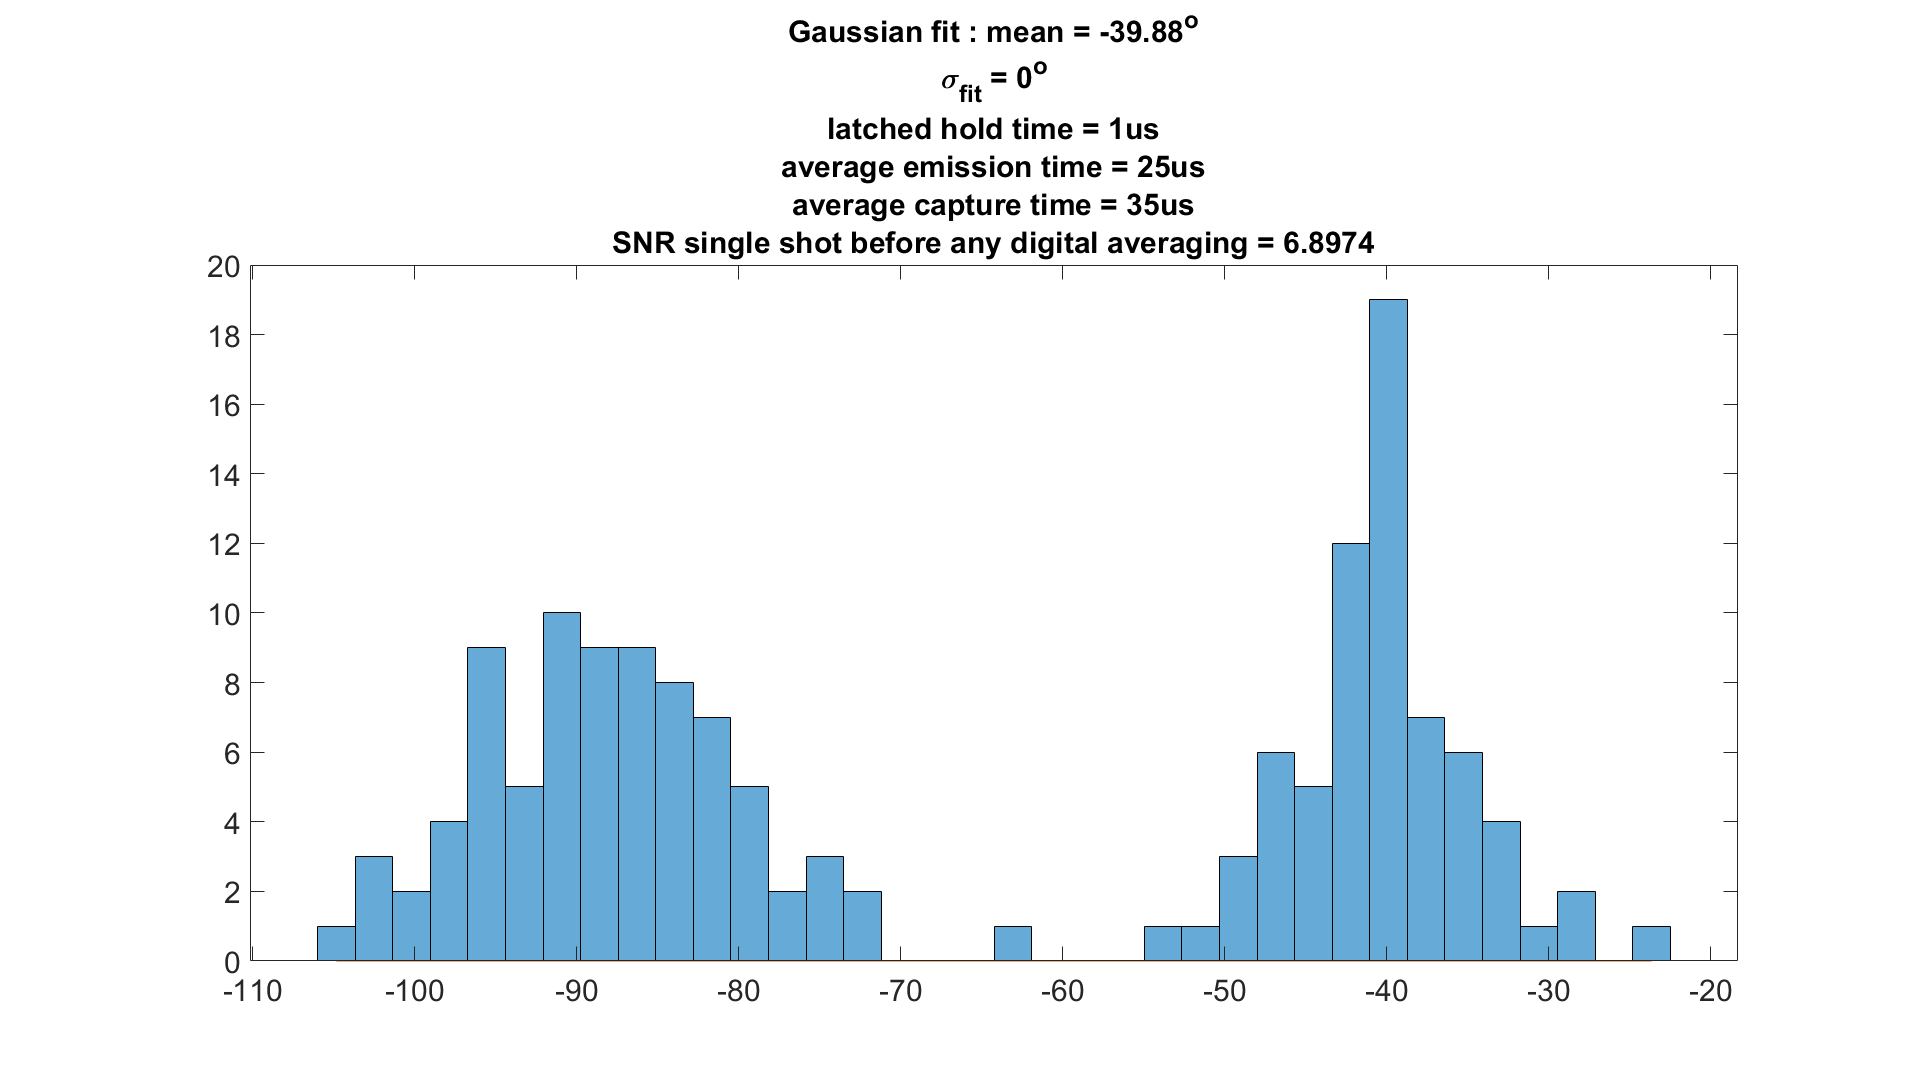

envelope_phase_total_reshaped = reshape(squeeze(envelope_phase_total(1,1:end - mod(length(time),sampling_freq/1e6))), round(average_number_latched), []);
envelope_phase_total_averaged_over_latch = circ_mean(envelope_phase_total_reshaped,[],1);
figure
averaged_histogram = histogram(180/pi*squeeze(envelope_phase_total_averaged_over_latch(1,:)), 36);
bin_width = averaged_histogram.BinWidth;
bin_edges = averaged_histogram.BinEdges;
[~,I] = max(averaged_histogram.Values);
peak_angle = bin_edges(I) + bin_width/2;
[gaussian_fit_averaged, theory_gaussian_averaged] = fit_gaussian(wrapTo180(bin_edges(1:end - 1) + bin_width/2 - peak_angle), averaged_histogram.Values);
hold on
plot(wrapTo180(bin_edges(1:end - 1) + bin_width/2), theory_gaussian_averaged)
title(['Gaussian fit : mean = ' num2str(gaussian_fit_averaged(2) + peak_angle) '^o' 13 10 ...
    '\sigma_{fit} = ' num2str(gaussian_fit_averaged(3)) '^o' 13 10 ...
    'latched hold time = ' num2str(latched_hold_time*1e6) 'us' 13 10 ...
    'average emission time = ' num2str(average_emission_time*1e6) 'us' 13 10 ...
    'average capture time = ' num2str(average_capture_time*1e6) 'us' 13 10 ...
    'SNR single shot before any digital averaging = ' num2str(snr_bw_limited_noise)])

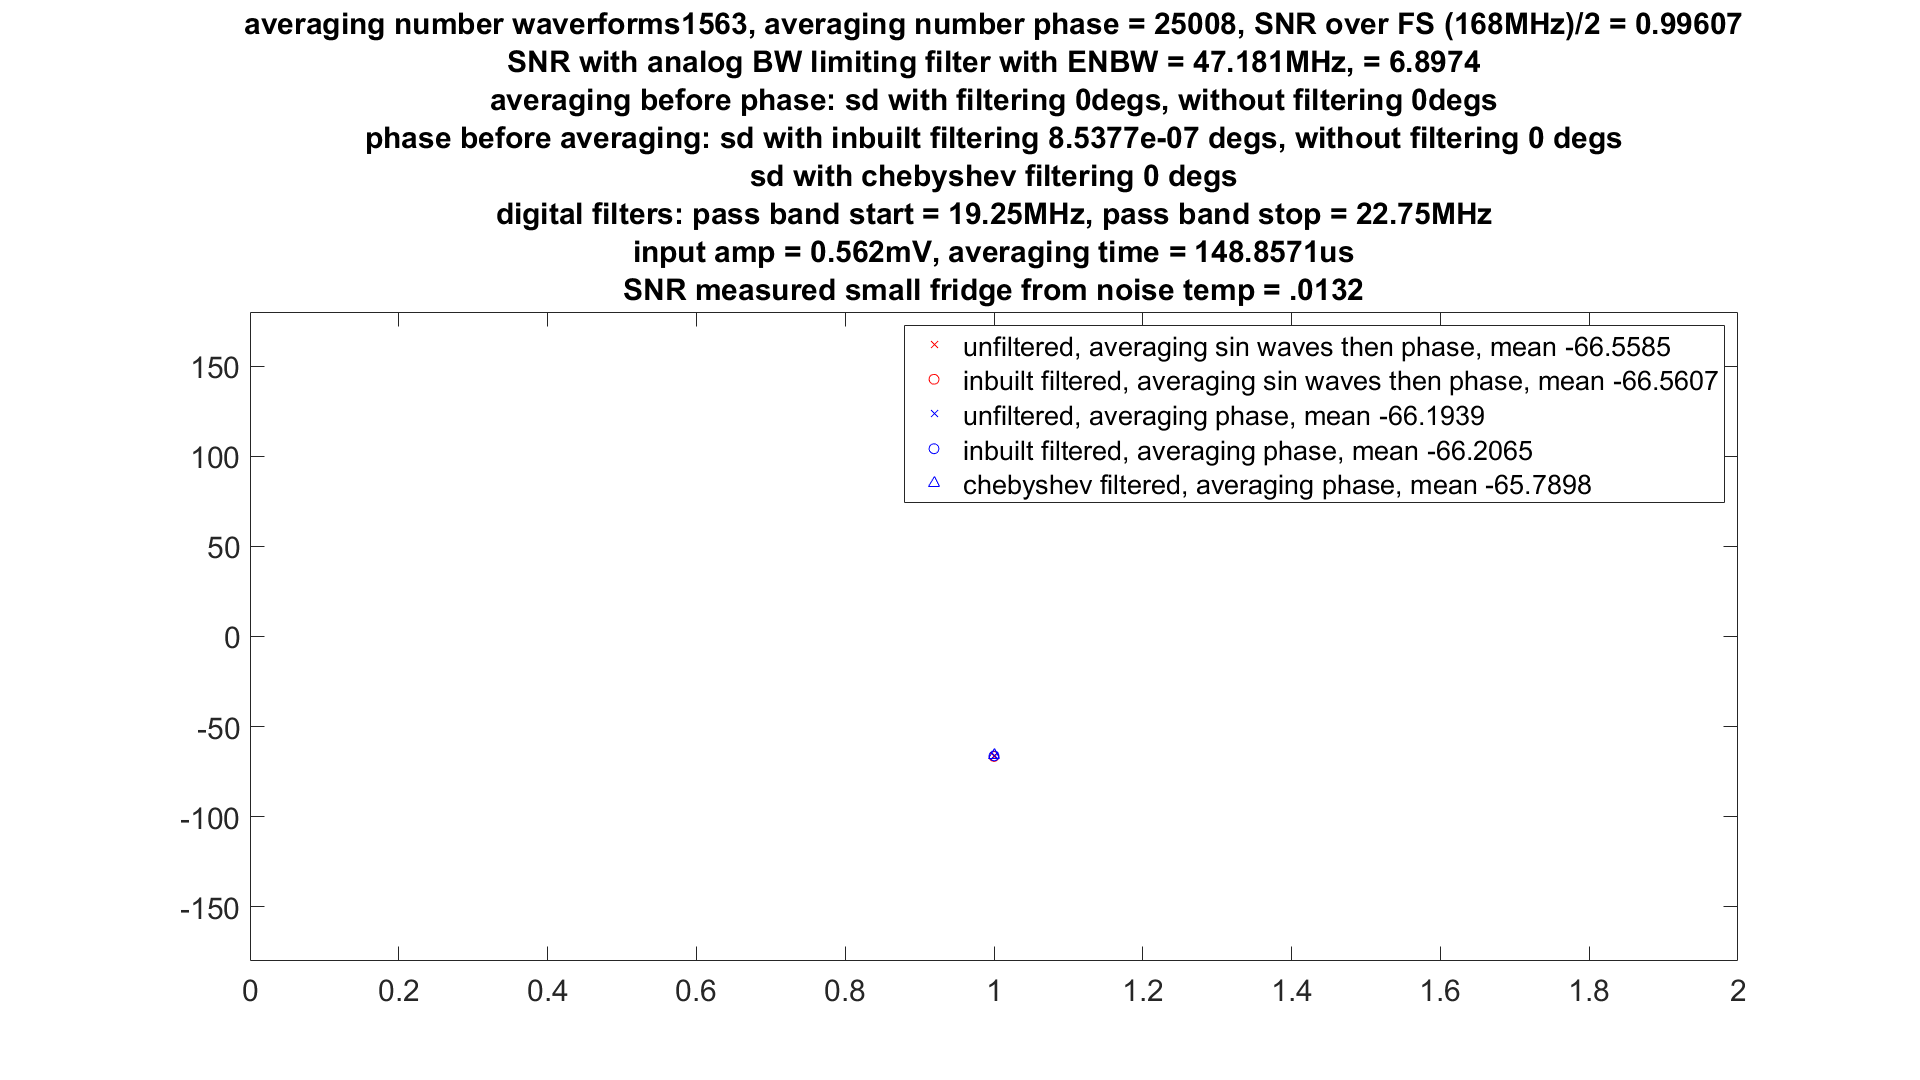

% plot extracted phases for each iteration
figure
plot(mean_phase,'rx', 'DisplayName', ['unfiltered, averaging sin waves then phase, mean ' num2str(iterations_mean_unfiltered_average_waveforms)])
hold on
plot(mean_phase_filtered_inbuilt,'ro', 'DisplayName', ['inbuilt filtered, averaging sin waves then phase, mean ' num2str(iterations_mean_filtered_inbuilt_average_waveforms)])
plot(mean_phase_total,'bx', 'DisplayName', ['unfiltered, averaging phase, mean ' num2str(iterations_mean_unfiltered_average_phases)])
plot(mean_phase_total_filtered_inbuilt,'bo', 'DisplayName', ['inbuilt filtered, averaging phase, mean ' num2str(iterations_mean_filtered_inbuilt_average_phases)])
plot(mean_phase_total_filtered_chebyshev, 'b^', 'DisplayName', ['chebyshev filtered, averaging phase, mean ' num2str(iterations_mean_filtered_chebyshev_average_phases)])
legend show
title(['averaging number waverforms' num2str(number_averages) ', averaging number phase = ' num2str(number_averages*16) ', SNR over FS (168MHz)/2 = ' num2str(snr_white_noise) ...
    13 10 'SNR with analog BW limiting filter with ENBW = ' num2str(enbw_bw_limited_noise) 'MHz, = ' num2str(snr_bw_limited_noise) 13 10 'averaging before phase: sd with filtering '...
    num2str(iterations_std_filtered_inbuilt_average_waveforms) 'degs, without filtering ' num2str(iterations_std_unfiltered_average_waveforms) 'degs' 13 10 'phase before averaging: '...
    'sd with inbuilt filtering ' num2str(iterations_std_filtered_inbuilt_average_phases) ' degs, without filtering ' num2str(iterations_std_unfiltered_average_phases) ' degs' 13 10 ...
    'sd with chebyshev filtering ' num2str(iterations_std_filtered_chebyshev_average_phases) ' degs' 13 10 ...
    'digital filters: pass band start = ' num2str(pass_band_start_chebyshev/1e6) 'MHz, pass band stop = ' num2str(pass_band_stop_chebyshev/1e6) 'MHz' 13 10 ...
     'input amp = ' num2str(sin_wave_amp*1e3) 'mV, averaging time = ' num2str(number_averages*16/168) 'us' 13 10 ...
    'SNR measured small fridge from noise temp = .0132'])
 axis([0 number_iterations + 1 -180 180])

% figure
% hold on
% plot(freqs_white(1,:), mean(psd_white,1), 'b','DisplayName',['Averaged over iterations white noise spec, SNR ' num2str(snr_white_noise)])
% plot(freqs(1,:), mean(psd,1), 'r','DisplayName',['Averaged over iterations bw limited noise spec, SNR ' num2str(snr_bw_limited_noise)])
% plot(freqs_noise_filtered_inbuilt(1,:), mean(psd_noise_filtered_inbuilt,1), 'k','DisplayName', ['Averaged over iterations inbuilt filtered signal, SNR ' num2str(snr_inbuilt_filtered_noise)])
% plot(freqs_noise_filtered_chebyshev(1,:), mean(psd_noise_filtered_chebyshev,1), 'g','DisplayName', ['Averaged over iterations Chebyshev filtered signal, SNR ' num2str(snr_chebyshev_filtered_noise)])
% plot(freqs(1,:), psd_perfect_bw_limited_filtered, '-.r', 'DisplayName', 'Perfect filter for BW limited noise')
% plot(freqs_noise_filtered_inbuilt(1,:), psd_perfect_inbuilt_filtered, '-.k', 'DisplayName','Perfect filter for inbuilt filter')
% plot(freqs_noise_filtered_chebyshev(1,:) , psd_perfect_chebyshev_filtered, '-.g', 'DisplayName', 'Perfect filter for Chebyshev filter')
% title(['power spectral density of noise at different stages ' 13 10 ...
%     'single shot snr of white noise = ' num2str(snr_white_noise) ', ENBW = ' num2str(enbw_white_noise) 'MHz, analog BW limited = ' num2str(snr_bw_limited_noise) ', ENBW = ' num2str(enbw_bw_limited_noise) 'MHz' 13 10 ...
%     'single shot snr of digital filtered: inbuilt = ' num2str(snr_inbuilt_filtered_noise) ', ENBW = ' num2str(enbw_inbuilt_filtered_noise) 'MHz, Chebyshev filter = ' num2str(snr_chebyshev_filtered_noise) ', ENBW = ' num2str(enbw_chebyshev_filtered_noise) 'MHz'])
% legend show

% figure
% i = randi(number_iterations);
% figure
% plot(averaged_signal(i,:), 'DisplayName', 'unfiltered averaged')
% hold on
% plot(clean_sin_wave(1:16),'DisplayName', 'clean input signal')
% plot(averaged_signal_filtered_inbuilt(i,:), 'DisplayName', 'filtered averaged')
% legend show
% title(['averaging number ' num2str(number_averages) ', SNR = ' num2str(snr_white_noise)])
% 
% figure
% plot(180/pi*envelope_phase_total(i,:), 'DisplayName', 'unfiltered phase')
% hold on
% plot(180/pi*envelope_phase_total_filtered_inbuilt(i,:), 'DisplayName', 'inbuilt filtered phase')
% plot(180/pi*envelope_phase_total_filtered_chebyshev(i,:), 'DisplayName', 'chebyshev filtered phase')
% title(['extracted phases for iteration number ' num2str(i)])
% 
% % [freqs_white, psd_white] = extract_PSD(time, noise_white(i,:));
% % [freqs, psd] = extract_PSD(time, noise(i,:));
% 
% % figure
% % plot(freqs(i,:),psd(i,:),'DisplayName', 'BW limited noise for particular iteration')
% % hold on
% % plot(freqs_white(i,:), psd_white(i,:), 'DisplayName', 'White noise for particular iteration')
% % plot(freqs_white(i,:), mean(psd_white,1), 'DisplayName','Averaged over iterations white noise spec')
% % plot(freqs(i,:), mean(psd,1), 'DisplayName','Averaged over iterations bw limited noise spec')
% % plot(freqs_noise_filtered_inbuilt(i,:), psd_noise_filtered_inbuilt(i,:), 'DisplayName', 'inbuilt filtered signal particular iteration')
% % plot(freqs_noise_filtered_chebyshev(i,:), psd_noise_filtered_chebyshev(i,:), 'DisplayName', 'Chebyshev filtered signal particular iteration')
% % plot(freqs_noise_filtered_inbuilt(i,:), mean(psd_noise_filtered_inbuilt,1), 'DisplayName', 'Averaged over iterations inbuilt filtered signal')
% % plot(freqs_noise_filtered_chebyshev(i,:), mean(psd_noise_filtered_chebyshev,1), 'DisplayName', 'Averaged over iterations Chebyshev filtered signal')
% % title(['power spectral density of noise for iteration number ' num2str(i)])
% % legend show
% 
% 
% 
% figure
% plot(time,noise(i,:),'DisplayName', 'BW limited noise for particular iteration')
% hold on
% plot(time, noise_white(i,:), 'DisplayName', 'White noise for particular iteration')
% plot(time, filtered_noise_inbuilt(i,:), 'DisplayName', 'inbuilt filtered noise particular iteration')
% plot(time, filtered_noise_chebyshev(i,:), 'DisplayName', 'Chebyshev filtered noise particular iteration')
% plot(time, clean_sin_wave, 'DisplayName', 'Clear sin wave')
% title(['Signal at various stages for iteration number ' num2str(i)])
% legend show
% 
% [~, phase_chebyshev_particular] = get_amp_and_phase(time, filtered_signal_chebyshev(i,:), if_freq, sampling_freq);
% [~, phase_clean_sin_particular] = get_amp_and_phase(time, clean_sin_wave, if_freq, sampling_freq);
% 
% figure
% plot(time, phase_chebyshev_particular, 'DisplayName', 'extracted phase from particular iteration chebyshev filtered signal')
% hold on
% plot(time, phase_clean_sin_particular, 'DisplayName', 'extracted phase clean sin wave')
% legend show
% 
% % figure
% % plot(noisy_signal(i,:)(1:96))
% % hold on
% % plot(filtered_signal(1:96))

% i = randi(number_iterations);
% figure
% plot(averaged_signal(i,:), 'DisplayName', 'unfiltered averaged')
% hold on
% plot(clean_sin_wave(1:16),'DisplayName', 'clean input signal')
% plot(averaged_signal_filtered_inbuilt(i,:), 'DisplayName', 'filtered averaged')
% legend show
% title(['averaging number ' num2str(number_averages), ', SNR = ' num2str(snr_white_noise)])
% 
% figure
% plot(180/pi*envelope_phase_total(i,:), 'DisplayName', 'unfiltered phase')
% hold on
% plot(180/pi*envelope_phase_total_filtered_inbuilt(i,:), 'DisplayName', 'inbuilt filtered phase')
% plot(180/pi*envelope_phase_total_filtered_chebyshev(i,:), 'DisplayName', 'chebyshev filtered phase')
% title(['extracted phases for iteration number ' num2str(i)])
% legend show
% 
% % [freqs_white, psd_white] = extract_PSD(time, noise_white(i,:));
% % [freqs, psd] = extract_PSD(time, noise(i,:));
% 
% figure
% plot(freqs(i,:),psd(i,:),'DisplayName', 'BW limited noise')
% hold on
% plot(freqs_white(i,:), psd_white(i,:), 'DisplayName', 'White noise')
% title(['power spectral density of noise for iteration number ' num2str(i)])
% 
% 
% % figure
% % plot(noisy_signal(i,:)(1:96))
% % hold on
% % plot(filtered_signal(1:96))
